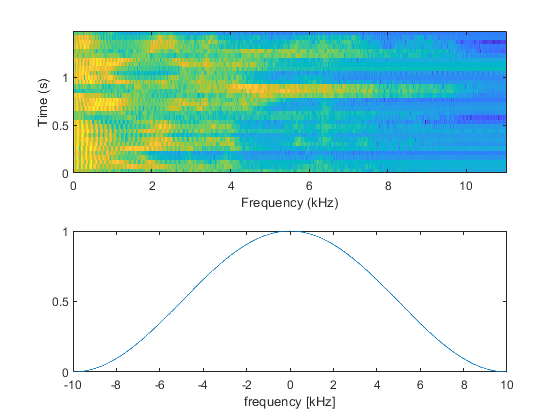

[x,fs] = audioread('example.wav'); x = x(0.1*fs:1.6*fs);
figure; subplot(2,1,1);spectrogram(x,1024,0,1024,fs); colorbar("off")
X = @(f) ((-10<f) & (f<10)).*cos(2*pi*f/40).^2; f = linspace(-10,10,1001);
subplot(2,1,2); plot(f,X(f)); xlabel('frequency [kHz]')

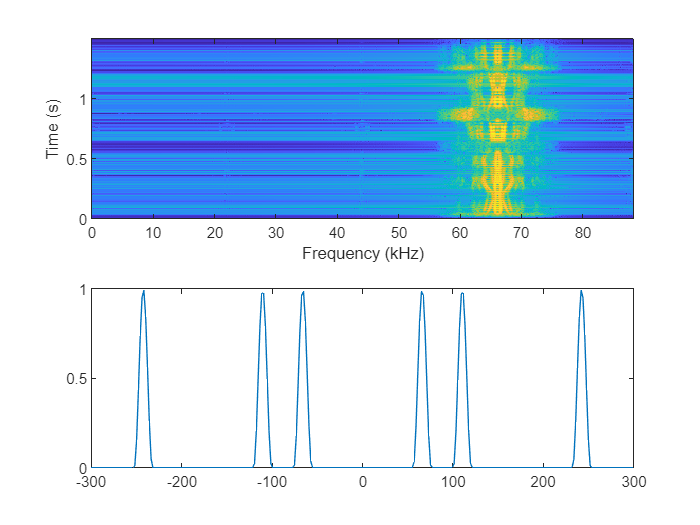

% N = 5; X2 = repmat(X,N,1); f2 = linspace(-N*fs/2,N*fs/2,N*length(x));
% figure; semilogy(f2/1000,X2); xlabel('frequency [kHz]')
x = resample(x,8,1); fs = 8*fs; fsk = fs/1000;
f0 = 3*fs/8; n=(1:length(x))'; y = x .* cos(2*pi*f0*n/fs);
figure; subplot(2,1,1); spectrogram(y,1024,0,1024,fs); colorbar("off")
f2 = linspace(-300,300,300); Y = @(f) X(f-66)+X(f+66);
subplot(2,1,2); plot(f2,Y(f2)+Y(f2-fsk)+Y(f2+fsk))

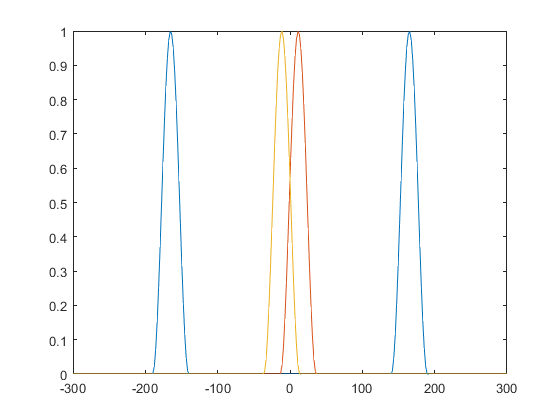

a = 0.4;
figure; plot(f2,Y(a*f2)); hold all;
plot(f2,Y(a*(f2-fsk)));
plot(f2,Y(a*(f2+fsk)));

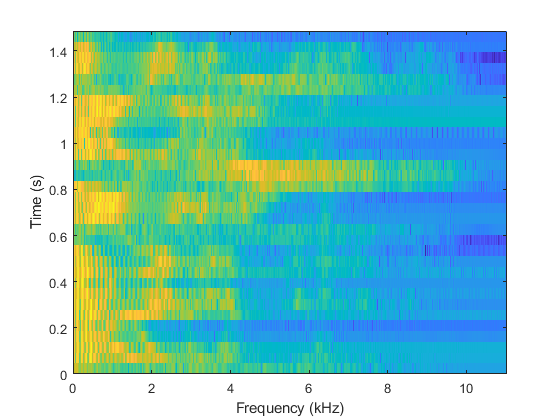

y2 = downsample(y,8);
figure; spectrogram(y2,1024,0,1024,fs/8); colorbar("off")